# EE 141: Digital Signal Processing

# Lab 7: FIR Filter Design Using DFT and Projection Onto Convex Sets

# Lab Section: 022

# Name: Buddy Ugwumba 

# SID: 862063029

## Objective

Design a discrete-time linear phase FIR filter  with the following specifications:

- $0\ldotp 98\le |H\left(e^{j\omega } \right)|\le 1\;\mathrm{for}\;0\le \omega \le 0\ldotp 25\pi$ and $1\ldotp 75\pi \le \omega \le 2\pi$

- $|H\left(e^{j\omega } \right)|\le 0\ldotp 02$ for $0\ldotp 5\pi \le \omega \le 1\ldotp 5\pi$

using the iterative design technique learned in class. Specifically the 512-point DFT. This alters our design specifications in the following manner.

- $0\ldotp 98\le \left|H\left(k\right)\right|\le 1\;\textrm{for}\;0\le k\le 64$ and $448\le k\le 511$

- $\left|H\left(k\right)\right|\le 0\ldotp 02$ for $128\le k\le 384$

Our desire is a type 1 linear phase FIR filter $h\left\lbrack n\right\rbrack$ of some relatively low order N matching these requirements. Therefore, $H\left\lbrack k\right\rbrack$ will always be of the form 


$$H\left\lbrack k\right\rbrack =e^{-j\frac{2\pi k}{512}*\frac{N}{2}} A\left\lbrack k\right\rbrack =e^{-j\frac{\pi \mathrm{kN}}{512}} A\left\lbrack k\right\rbrack$$


Since $H\left\lbrack k\right\rbrack$ will always be in the above form, It suffices to apply the design requirements to $A\left\lbrack k\right\rbrack$

- $0\ldotp 98\le A\left(k\right)\le 1\;\textrm{for}\;0\le k\le 64$ and $448\le k\le 511$

- $A\left(k\right)\le 0\ldotp 02$ for $128\le k\le 384$

1) Set N = 10

% Order of the initial value
clear;
N = 20;

2) Initialize with $A\left\lbrack k\right\rbrack =1$ for all $0\le k\le 64$ and $448\le k\le 511$, and $A\left\lbrack k\right\rbrack =0$ for all other k.

% This is the pass band area where we convert omega to k
for k = 1:65
    A(k) = 1;
end

% This is the second pass band
for k = 449:512
    A(k) = 1;
end

% This is the stop band
for k = 66:448
    A(k)= 0;
end

3) Computer the 512-point interse DFT of $H\left\lbrack k\right\rbrack =e^{-j\frac{\pi \mathrm{kN}}{512}} A\left\lbrack k\right\rbrack$ using the ifft command, and set it to $g\left\lbrack n\right\rbrack$

h_o = zeros(1, 512);
x = 0;
h_n = zeros(1, 512);
k = 0:511;
% DFT of h[n]
H_k = exp((-1i*pi*k*N)/512).*A; 
% Inverse DFT
g_n = ifft(H_k);

4) Set


$$h\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{cc}
g\left\lbrack n\right\rbrack  & 0\le n\le N\\
0 & \mathrm{otherwise}
\end{array}\right.$$


h_o = h_n;
h_n(1:N+1) = g_n(1:N+1);

5) Set =  $H\left\lbrack k\right\rbrack =\mathrm{DFT}\left\lbrace h\left\lbrack n\;\right\rbrack \right\rbrace$ using the fft command

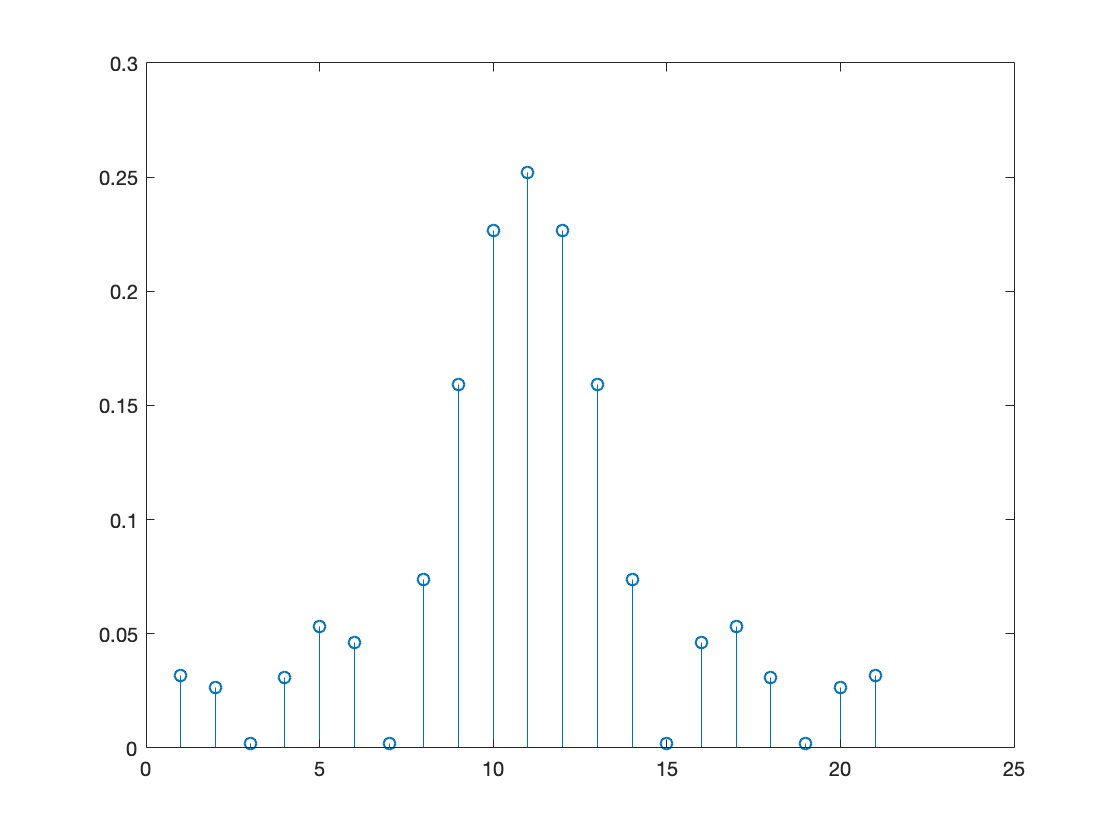

% DFT
H_k = fft(h_n);
figure
stem(abs(h_n(1:N+1)))

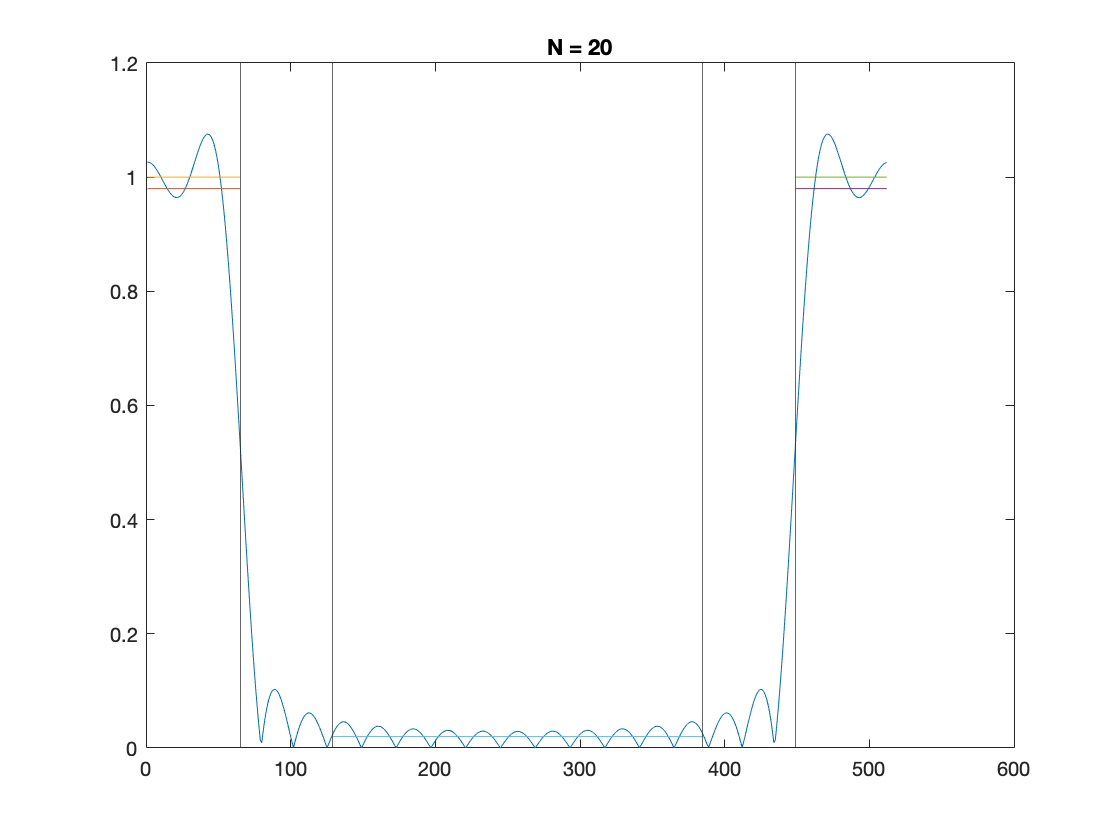

figure
plot(abs(H_k))
hold on;
plot([1,65], [0.98,0.98]);
plot([1,65], [1,1]);
plot([449,512], [0.98,0.98]);
plot([449,512], [1,1]);
plot([129,385], [0.02, 0.02]);
xline(65);
xline(129);
xline(449);
xline(385);
title(sprintf('N = %d', N));

6) Set $B\left\lbrack k\right\rbrack =H\left\lbrack k\right\rbrack e^{j\frac{\pi \mathrm{kN}}{512}}$

B_k = H_k.*exp((1i*pi*k*N)/512);

7) Clip $B\left\lbrack k\right\rbrack$ wherever it violates the specifications above and set the clipped version to $A\left\lbrack k\right\rbrack$. That is, for $0\le k\le 64\;$or $44\le k\le 511$.


$$\begin{array}{l}
A\left\lbrack k\right\rbrack =\;\left\lbrace \begin{array}{cc}
B\left\lbrack k\right\rbrack  & 0\ldotp 98\le B\left\lbrack k\right\rbrack \le 1\\
1 & B\left\lbrack k\right\rbrack >1
\end{array}\right.\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\ldotp 98\;\;\;\;\;\;\;B\left\lbrack K\right\rbrack <0\ldotp 98
\end{array}$$


The internal $128\le k\le 384$ should be treated similarly. For all remaining K values, $\;A\left\lbrack k\right\rbrack =B\left\lbrack k\right\rbrack \ldotp$

A = B_k;
for k = 1:65
    if B_k(k) > 1
        A(k) = 1;
    end
    if B_k(k) < 0.98
        A(k) = 0.98;
    end
end

for k = 449:512
    if B_k(k) > 1
        A(k) = 1;
    end
    if B_k(k) < 0.98
        A(k) = 0.98;
    end
end

for k = 129:385
    if B_k(k) > 0.02
        A(k) = 0.02;
    end
    if B_k(k) < -0.02
        A(k) = -0.02;
    end
end

## For some reason my while loop is not working


while(1)
    k = 0:511;
    h_k = exp((-1i*pi*k*N)/512).*A;
    g_n = ifft(H_k);
    
    %iteratio of step 4
    h_o = h_n;
    h_n(1:N+1) = g_n(1:N+1);
    %distance between the original and the new h_n
    delta_h_n = sum((h_o - h_n).^2);
    if delta_h_n < 0.00000000000001
        break
    elseif delta_h_n < 0.001
        N = N+2;
        continue
    end
    
    % Iteration of step 5
    H_k = fft(h_n);
    x = x+1;
    if x == 21
        x = 0;
    end
    
    %Plots some of the filter
    if(mod(x,10)==1)
        figure
        stem(abs(h_n(1:N+1)))
        figure
        plot(abs(H_k))
        hold on;
        plot([1,65], [0.98,0.98]);
        plot([1,65], [1,1]);
        plot([449,512], [0.98,0.98]);
        plot([449,512], [1,1]);
        plot([129,385], [0.02, 0.02]);
        xline(65);
        xline(129);
        xline(449);
        xline(385);
        title(sprintf('N = %d', N));
    end
    
    % iteration of step 6
    B_k = H_k.*exp((1i*pi*k*N)/512);
    
    %iteration of step 7
    A = B_k;
    for k = 1:65
        if B_k(K) > 1
            A(k) = 1;
        end
        if B_k(k) < 0.98
            A(k) = 0.98;
        end
    end

    for k = 449:512
        if B_k(k) > 1
            A(K) = 1;
        end
        if B_k(k) < 0.98
            A(k) = 0.98;
        end
    end

    for k = 129:385
        if B_k(k) > 0.02
            A(k) = 0.02;
        end
        if B_k(k) < -0.02
            A(k) = -0.02;
        end
    end
end